## Introduction

The following MATLAB live script is an example for implementation of classes "corrugated_isotropic" and "corrugated_composite" used to analyze the bending and free vibration response of a corrugated core sandwitch plates.

## Corrugation Geometry

The folllwing corrugation geometry convention was followed when analyzing a 300 [mm] x 300 [mm] plate.

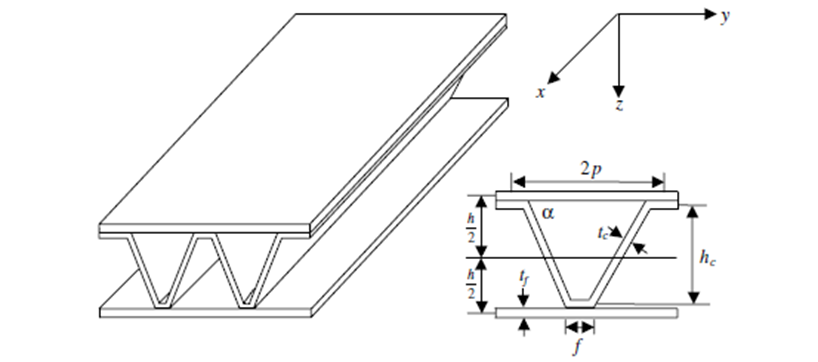

Assign corrugation geometry for test panel.

geom        = struct;   % initialize structure
geom.theta  = 60;       % corruation angel [deg]
geom.a      = 300/1000; % plate width [m]
geom.b      = geom.a;   % plate length [m]
geom.h_c    = 25/1000;  % corrugation height [m]
geom.p      = 25/1000;  % corrugation pitch [m]
geom.t_f    = 2.5/1000; % face sheet thickness [m]
geom.t_c    = 2.5/1000; % corrugation sheet thickness [m]

## Isotropic Material Properties and Implementation

The following code assignes the material properties of an isotropic materil (steel) for analysis with the "corrugated_isotropic" class.

steel_props       = struct;   % initialize material properties structure
steel_props.E_c   = 200e9;    % Corrugation core young's modulus [Pa]
steel_props.E_f   = 200e9;    % Face sheets young's modulus [Pa]
steel_props.v_f   = 0.25;     % Face sheet poisson's ratio [-]
steel_props.v_c   = 0.25;     % Core poiton's ratio [-]
steel_props.rho   = 7.872e-06*(1000)^3; % Density [kg/m3]

steel_example = corrugated_isotropic;          % Intialize object to analyze isotorpic material
steel_example = steel_example.def_geom(geom);  % Assign corrugation geometry via def_geom method
steel_example = steel_example.def_mat_props(steel_props); % Assign material properties via def_mat_props method
steel_example = steel_example.calc_stiffness;   % Calculate equilvanet stiffness via calc_stiffness method
steel_example = steel_example.Modal_Analysis;   % perform modal analysis per modal_analysis method
steel_example = steel_example.Bending_Analysis(1000);   % analyze bending response to 1000 N/m2 pressure load

Display the results for natual frequency and maximum deflection from bending load

disp(steel_example.w_n) % Display equivalent plate natural frequency [Hz]

   1.6301e+03



disp(max(max(steel_example.bending_rslt.w))) % Display maximum deflection from bending load [m]

   2.1829e-07



## Cross Ply Laminate Material Properties and Implementation

The following code assignes the material properties of an cross ply laminate for analysis with "corrugated_composite" class.

fiberglass       = struct;      % initialize structure for fiberglass material properties
fiberglass.E1    = 34.75e9;     % assign young's modulus in 0 degree direction [Pa]
fiberglass.E2    = 7.86e9;      % assign young's modulus in 90 degree direction [Pa]
fiberglass.v12   = 0.278;       % assign major poisson's ratio [-]
fiberglass.v21   = fiberglass.v12*fiberglass.E2/fiberglass.E1;  % calculate minor poissons ratio from orthotropic material relations
fiberglass.G12   = 10.96e9;     % assign shear modulus [Pa]
fiberglass.rho   = 2370;        % assign density [kg/m3]

cross_ply_example = corrugated_composite;               % initialize object of class corrugated composite
cross_ply_example = cross_ply_example.def_geom(geom);   % define corrugation geometry with method 
cross_ply_example = cross_ply_example.def_mat_props(fiberglass); % define material properties
cross_ply_example = cross_ply_example.calc_stiffness;   % method to calculate equivalent plate stiffness
cross_ply_example = cross_ply_example.Modal_Analysis;   % method to perform modal analysis
cross_ply_example = cross_ply_example.Bending_Analysis(1000) % analyze bending response to 1000 N/m2 pressure load

cross_ply_example =   corrugated_composite with properties:

            geom: [1×1 struct]
       mat_props: [1×1 struct]
       equ_props: [1×1 struct]
               D: [1×1 struct]
               M: 1
               N: 1
         L_eff_x: 1
         L_eff_y: 1
             w_n: 985.5292
    bending_rslt: [1×1 struct]
        wn_strip: 3.3989e+03


Display the results for natual frequency and maximum deflection from bending load

disp(cross_ply_example.w_n) % Display equivalent plate natural frequency [Hz]

  985.5292



disp(max(max(cross_ply_example.bending_rslt.w))) % Display maximum deflection from bending load [m]

   1.9840e-06

